# Reading the values from the exported .mat file (RaceStudio2)


lon = L001_longitude;
lat = L001_latitude;
heigth = L001_altitude;
distance = L001_distance;


## Calculate UTM Zone (Universal Transverse Mercator coordinate system)


z1 = utmzone(lat(1),lon(1));


## Convert Data to UTM


[ellipsoid,estr] = utmgeoid(z1);
utmstruct = defaultm('utm');
utmstruct.zone = z1;
utmstruct.geoid = ellipsoid;
utmstruct = defaultm(utmstruct);

[x,y] = mfwdtran(utmstruct,lat,lon);


## Normalize Data to Zero (minimum of x and y)


% Normalize x, y and z coordinates
x_norm = x-min(x);
y_norm = y-min(y);
heigth_norm = heigth-min(heigth);

% distance_x = max(lat)-min(lat)
% distance_y = max(lon)-min(lon)

% Plot normalized data
%plot(x_norm,y_norm)
%plot(heigth_norm)


## Create Single Lap from data


% Start and finish point of a single lap
start = 1287;
finish = 2185;

% complete data for one lap
x_lap = x_norm(start:finish);
y_lap = y_norm(start:finish);
z_lap = heigth_norm(start:finish);
distance_lap = distance(start:finish)-min(distance(start:finish));

X = [x_lap, y_lap];

[L2,R2,K2] = curvature(X);

R2(1) = R2(2);
R2(end) = R2(end-1);

% Save track file
Track = [x_lap, y_lap, z_lap, distance_lap, R2];


## Plot created Track

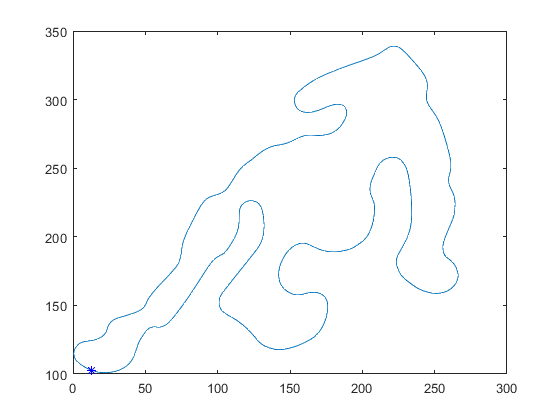


plot(x_lap, y_lap)
hold on

% Mark start point
plot(x_norm(start),y_norm(start),'r*')

% Mark end point 
plot(x_norm(finish),y_norm(finish),'b*')

hold off

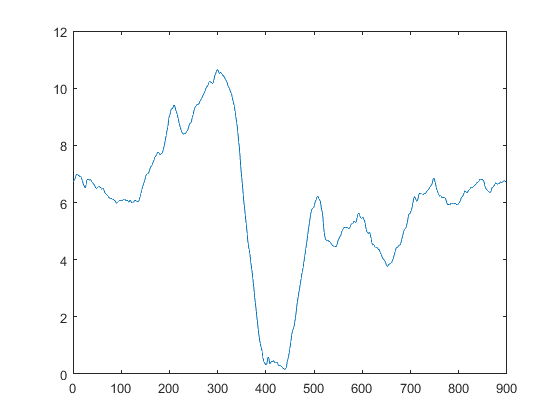


% Plot Elevation
plot(z_lap);

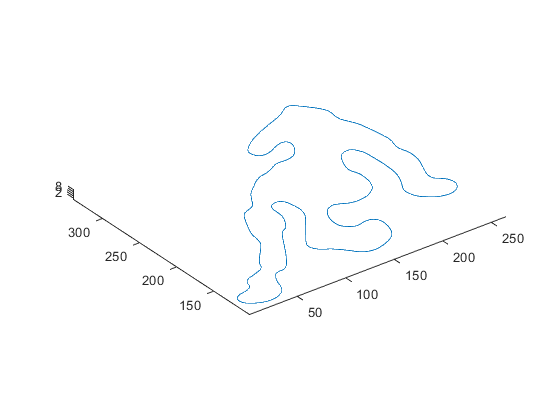


% 3D track plot
plot3(x_lap, y_lap, z_lap)
axis equal



% load enso
% f = fit(x_lap,y_lap,'smoothingspline');
% plot(f,x_lap,y_lap)



function [L,R,k] = curvature(X)
% Radius of curvature and curvature vector for 2D or 3D curve
%  [L,R,k] = curvature(X)
%   X:   2 or 3 column array of x, y (and possibly z) coordiates
%   L:   Cumulative arc length
%   R:   Radius of curvature
%   k:   Curvature vector
% The scalar curvature value is 1./R
% Version 2.6: Calculates end point values for closed curve
  N = size(X,1);
  dims = size(X,2);
  if dims == 2
    X = [X,zeros(N,1)];  % Use 3D expressions for 2D as well
  end
  L = zeros(N,1);
  R = NaN(N,1);
  k = NaN(N,3);
  for i = 2:N-1
    [R(i),~,k(i,:)] = circumcenter(X(i,:)',X(i-1,:)',X(i+1,:)');
    L(i) = L(i-1)+norm(X(i,:)-X(i-1,:));
  end
  if norm(X(1,:)-X(end,:)) < 1e-10 % Closed curve. 
    [R(1),~,k(1,:)] = circumcenter(X(end-1,:)',X(1,:)',X(2,:)');
    R(end) = R(1);
    k(end,:) = k(1,:);
    L(end) = L(end-1) + norm(X(end,:)-X(end-1,:));
  end
  i = N;
  L(i) = L(i-1)+norm(X(i,:)-X(i-1,:));
  if dims == 2
    k = k(:,1:2);
  end
end

function [R,M,k] = circumcenter(A,B,C)
% Center and radius of the circumscribed circle for the triangle ABC
%  A,B,C  3D coordinate vectors for the triangle corners
%  R      Radius
%  M      3D coordinate vector for the center
%  k      Vector of length 1/R in the direction from A towards M
%         (Curvature vector)
  D = cross(B-A,C-A);
  b = norm(A-C);
  c = norm(A-B);
  if nargout == 1
    a = norm(B-C);     % slightly faster if only R is required
    R = a*b*c/2/norm(D);
    return
  end
  E = cross(D,B-A);
  F = cross(D,C-A);  
  G = (b^2*E-c^2*F)/norm(D)^2/2;
  M = A + G;
  R = norm(G);  % Radius of curvature
  if R == 0
    k = G;
  else
    k = G'/R^2;   % Curvature vector
  end
end
